# Weighted norm of correlation

**Author**: Abakumov Ivan

Freie Universität Berlin

**E-mail: **abakumov_ivan@mail.ru

**Publication date**: 29th of November, 2016

## Introduction

See paper: 

Van Leeuwen, Tristan, and W. A. Mulder. "A correlation-based misfit criterion for wave-equation traveltime tomography." Geophysical Journal International 182.3 (2010): 1383-1394.

The authors propose to find the relative phase shift between two waveforms via maximization of the weighted norm of correlation. See eq. 17 in the paper. 

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Waveforms without phase rotation

First, I will reproduce some results of the paper. I create two wavefroms with Ricker wavelet with a 10 Hz peak frequency that are phase shifted by $\Delta T = 0.1s$: 

G.nt = 1001;                
G.dt = 0.001;               
btrace = zeros(1, G.nt);
mtrace = zeros(1, G.nt);

t = 0:0.001:0.3;
fpeak = 10; 
wt = ricker(fpeak,t); 

btrace(350:650) = wt;
mtrace(450:750) = wt; 

ub = btrace;
um = mtrace;

ub = ub - mean(ub);
um = um - mean(um);
   
C = xcorr(um,ub)/sqrt(sum(ub.^2)*sum(um.^2));

In this example maximum of correlation coinsides with the real phase shift indicated by the red line

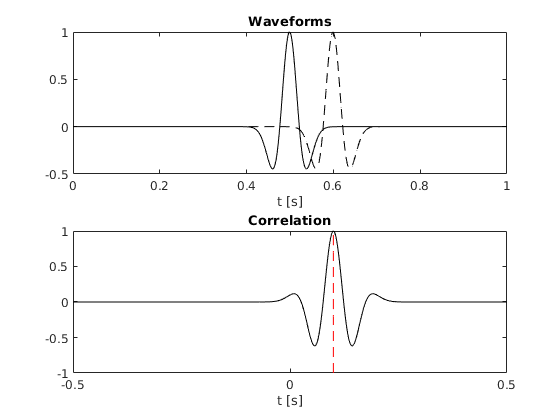

figure(1)
subplot(2,1,1)
plot(0:0.001:1, btrace, 'black')
hold on
plot(0:0.001:1, mtrace, '--black')
axis([0,1,-0.5,1]); 
title('Waveforms')
xlabel('t [s]');

subplot(2,1,2)
plot(-1:0.001:1, C, 'black'); 
hold on 
plot(0.1*ones(1,21), -1:0.1:1, '--red');
axis([-0.5, 0.5, -1, 1]); 
xlabel('t [s]');
title('Correlation')

## Waveforms with phase rotation

Now I consider the traces with phase rotation $\pi/2$: 

phaserotation = pi/2; 
mtrace = add_phase_rotation(mtrace,phaserotation); 
mtrace = mtrace/max(abs(mtrace));

ub = btrace;
um = mtrace;

ub = ub - mean(ub);
um = um - mean(um);
   
C = xcorr(um,ub)/sqrt(sum(ub.^2)*sum(um.^2));

Crosscorrelation in this case leds to wrong value of the phase shift: 

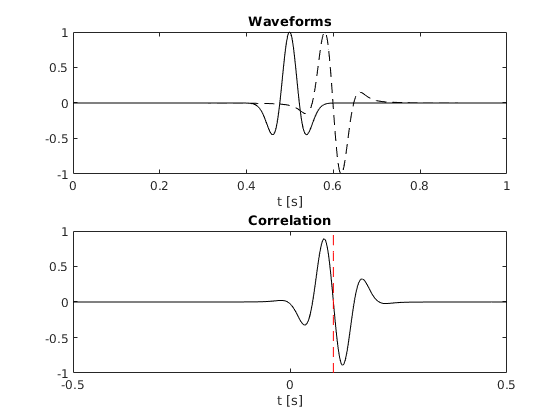

figure(2)
subplot(2,1,1)
plot(0:0.001:1, btrace, 'black')
hold on
plot(0:0.001:1, mtrace, '--black')
axis([0,1,-1,1]); 
title('Waveforms')
xlabel('t [s]');

subplot(2,1,2)
plot(-1:0.001:1, C, 'black');
hold on 
plot(0.1*ones(1,21), -1:0.1:1, '--red');
axis([-0.5, 0.5, -1, 1]); 
xlabel('t [s]');
title('Correlation')

## Weighted norm of correlation

The weighted norm of correlation (see eq. 17) still returns stable result. For this example I took Gaussian weight (see eq. 15) with $t0 = 0.1s$

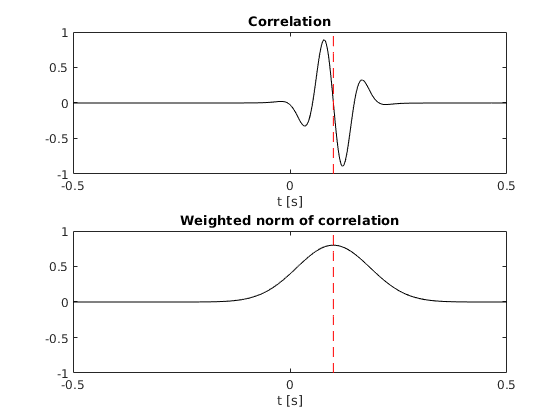

W = exp(-(linspace(-10,10,length(C))).^2); 
     
tt = -1:0.001:1; 
w = 2*pi*fpeak; 
CC = C.*exp(-1i*w*tt); 
J = abs(xcorr(CC,W));

figure(3)
subplot(2,1,1)
plot(-1:0.001:1, C, 'black');
hold on 
plot(0.1*ones(1,21), -1:0.1:1, '--red');
axis([-0.5, 0.5, -1, 1]); 
xlabel('t [s]');
title('Correlation')

subplot(2,1,2)
plot(-2:0.001:2, J/max(1.25*J), 'black')
hold on 
plot(0.1*ones(1,21), -1:0.1:1, '--red');
axis([-0.5, 0.5, -1, 1]); 
xlabel('t [s]');
title('Weighted norm of correlation')